# Data_Calibration: Mask_Calib & Meas_Calib

## Init

clc, clear, addpath('./util')

## params

% data_20210315
% background and lumination
bkg_path =  "E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\black_white\black.tif" % bakcground path

bkg_path = "E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\black_white\black.tif"

illum_path = "E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\black_white\white.tif" % illumination path

illum_path = "E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\black_white\white.tif"

meas_bkg_path = "E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\black_white\scene_black.tif"; % scene background path

% mask and meas
mask_path = 'E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\#calib_mask_aver\'

mask_path = 'E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\#calib_mask_aver\'

meas_path = 'E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\scene\'

meas_path = 'E:\project\SCI_captioning\experiment\real_data\test\SCICAP_binary_mask_Cr8_20211011\scene\'

meas_names  = ["AVG_static_car.tif"]; % 'all' || 'xxx'

time_stamp = '20211011'

time_stamp = '20211011'



% saving setting
data_save_path = meas_path;

file_format = '.tif';
% file_format = '.mat';

Cr = 8;
% mask_size = [3200,3200]
% mask_size = [2048,2048]
% mask_size = [1024,1024]
% mask_size = [1000,1000]
% mask_size = [800,800]
mask_size = [512,512]

mask_size =    512   512


% mask_size = [400 400]
% mask_size = [256,256]

% roi_rect = [1540,2680,mask_size(2)-1, mask_size(1)-1];  % 1204
roi_rect = [1 1 mask_size(2)-1 mask_size(1)-1];  % 1204

% flags
save_sep_mask = 0;
save_sep_meas = 1; % for dealing with multiple measurements
write_meas_img = 1;

% FOR: multi measurements saved in one file (save_sep_meas=0),setting the
% file name
if ~save_sep_meas
    dataname = input("Input dataset saving name: "); 
end

% ---
% meas_path = char(meas_path);



## load image

% background and  lumi
bkg_img = single(imread(bkg_path));
illum_img = single(imread(illum_path));
meas_bkg_img = single(imread(meas_bkg_path));

% mask
masks = dir([mask_path '*' file_format]);
mask_names = {masks.name};
mask_num = numel(mask_names);
disp([num2str(mask_num) ' masks found'])

8 masks found



if(mask_num~=Cr)
    error('mask amount != Cr')    
end

src_mask = zeros([size(illum_img),Cr]);
for k = 1:Cr
    if strcmp(file_format, '.tif')
        src_mask(:,:,k) = single(imread([mask_path mask_names{k}]));
    elseif strcmp(file_format, '.mat')
        tmp_img = load([mask_path mask_names{k}]);
        src_mask(:,:,k) = tmp_img.img;
    end
end

% meas
if ~exist('meas_names','var') || ismember("all", meas_names)
    meass = dir([meas_path '*.tif']);
    meas_names = {meass.name};
end
meas_num = numel(meas_names);

disp([num2str(meas_num) ' measurements found'])

1 measurements found



src_meas = zeros([size(illum_img),meas_num]);
for k = 1:meas_num
    % read
    if exist('meas_names','var')
        meas_name = meas_names{k};
    else
        meas_name = file_names{k};
    end

    src_meas(:,:,k) = single(imread([char(meas_path) meas_name]));
end


## mask: crop, de_background, de_illumination

% bkg and white
crop_bkg = imcrop(bkg_img, roi_rect);
crop_illum = imcrop(illum_img, roi_rect);


debkg_crop_illum = crop_illum - crop_bkg;
if(min(debkg_crop_illum, [],'all')<=0)
    warning('debkg_crop_white_nomask<=0, press eny key to continue...')
    pause
end

crop_mask= zeros([mask_size,Cr]);
% crop
for k = 1:Cr
    crop_mask(:,:,k) = imcrop(src_mask(:,:,k), roi_rect);
end
% de_bkg
debkg_crop_mask = crop_mask - crop_bkg;
% de_lumi
delumi_debkg_crop_mask = debkg_crop_mask./debkg_crop_illum;
delumi_crop_mask = crop_mask./crop_illum;


% % show
% imshow(crop_mask(:,:,k),[])
% title('crop\_mask')
% figure
% imshow(debkg_crop_mask(:,:,k),[])
% title('debkg_crop\_mask')
% figure
% imshow(delumi_debkg_crop_mask(:,:,k),[])
% title('delumi_debkg_crop\_mask')

if(min(delumi_debkg_crop_mask, [],'all')<=0)
    warning('delumi_debkg_crop_mask<=0, press eny key to continue...')
    pause
end

preproc_mask = delumi_debkg_crop_mask; % crop, de_background, de_illumination
% preproc_mask = debkg_crop_mask; % crop, de_background, de_illumination


## mask: normalize

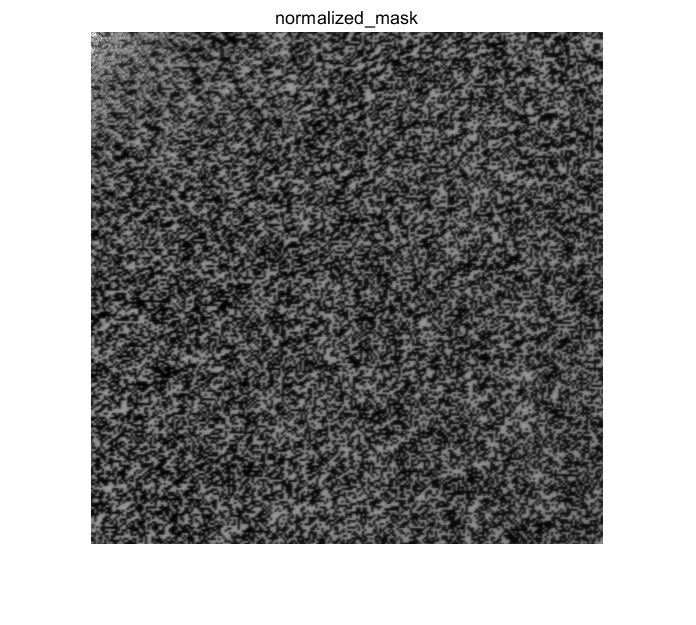

% normallize to 0-1
non_norm_mask = preproc_mask;
mask = preproc_mask;
mask_max = max(mask, [],'a');
mask = mask./mask_max;

imshow(mask(:,:,1),[]);
title('normalized\_mask')

## mask: analysis, show

% corr matrix
[corr_v, ~, corr_v_aver, ~]= matrix_corr(mask);

disp(['average corr: ' num2str(corr_v_aver)])

average corr: 0.020417


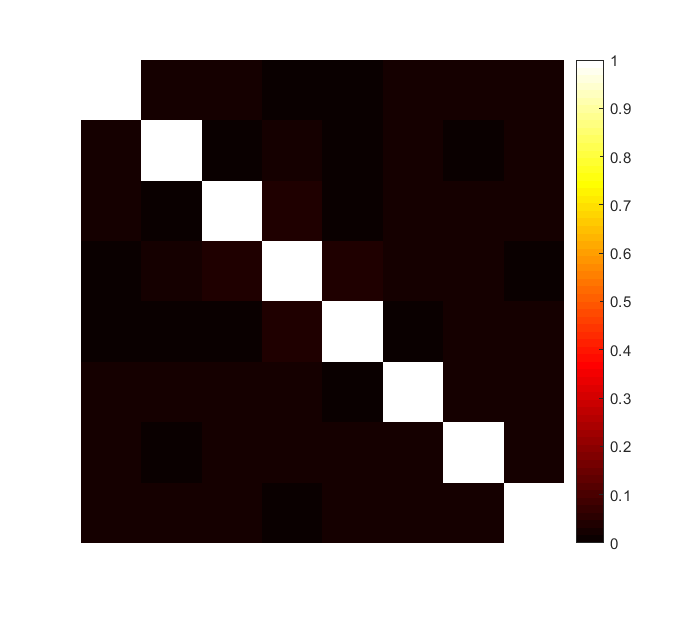


imshow(corr_v, 'InitialMagnification','fit')
colormap('hot')
colorbar()

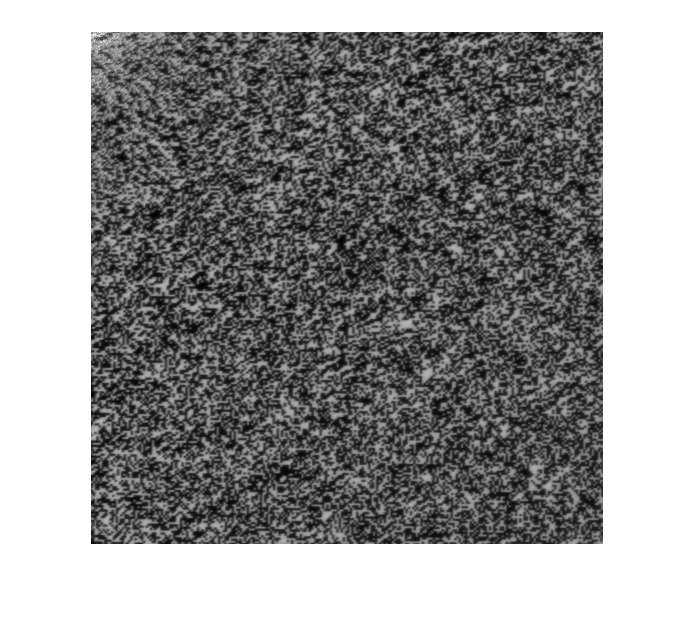


% mask corr sort
corr_v_mean = (sum(corr_v)-1)/(size(corr_v, 2)-1);
[corr_v_sort, corr_v_sort_idx] = sort(corr_v_mean);

% show
figure
for k = 1:Cr
%     figure
    imshow(mask(:,:,k),[])
    drawnow
end

## mask: save

if save_sep_mask
    % save mask
    mask_save_name = ['calib_mask_circ_cap_' time_stamp '_roi' num2str(roi_rect(1)) '-' num2str(roi_rect(2)) '_sz' num2str(mask_size(2))]
    save([mask_path,mask_save_name,'.mat'], 'mask', 'non_norm_mask' ,'src_mask','crop_mask','debkg_crop_mask','delumi_debkg_crop_mask', 'delumi_crop_mask', '-v7.3');
    % save([save_path,save_name,'.mat'], 'mask', 'non_norm_mask' ,'src_mask','crop_mask','debkg_crop_mask','delumi_debkg_crop_mask', 'illum_img','bkg_img','crop_mask', '-v7.3');


end


## meas: crop, debkg, analysis, show

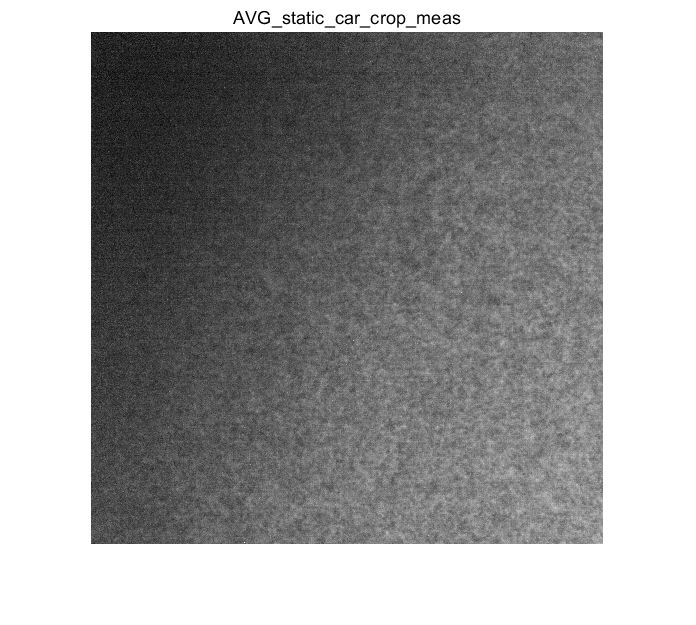

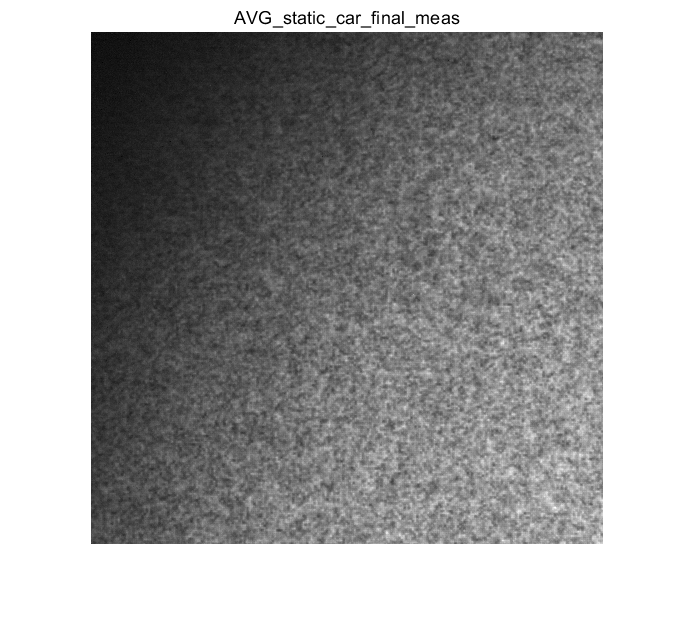

MEAS: max 3357.00, mean 1194.00, min -184.00

crop_meas_bkg = imcrop(meas_bkg_img, roi_rect);

crop_meas= zeros([mask_size,meas_num]);

for k = 1:meas_num
    if exist('meas_names','var')
        meas_name = meas_names{k};
    else
        meas_name = file_names{k};
    end  
    
    % crop
    
    crop_meas(:,:,k) = imcrop(src_meas(:,:,k), roi_rect);

    % de_bkg
    debkg_crop_meas = crop_meas - crop_meas_bkg;

    % final meas
    meas = debkg_crop_meas;
    % meas = crop_meas;

    % show
    figure
    imshow(crop_meas(:,:,k),[])
    title([meas_name(1:end-4) '_crop_meas'], 'Interpreter', 'none')
    figure
    imshow(meas(:,:,k),[])
    title([meas_name(1:end-4) '_final_meas'], 'Interpreter', 'none')

    % meas analysis
    mean_meas = mean(meas(:,:,k), 'all');
    max_meas = max(meas(:,:,k), [],'all');
    min_meas = min(meas(:,:,k), [],'all');
    fprintf('MEAS: max %.2f, mean %.2f, min %.2f', max_meas, mean_meas, min_meas)
end

## save data and image

% save data
if ~exist(data_save_path, 'dir')
    mkdir(data_save_path)
end

%---- save all measurements in one .mat file ----
if ~save_sep_meas
    data_save_name = ['data_' dataname '_' time_stamp '_roi' num2str(roi_rect(1)) '-' num2str(roi_rect(2)) '_sz' num2str(mask_size(2)) '_Cr' num2str(Cr)] ;
    write_name = [data_save_name '_%dth_meas'];
    
    save([data_save_path,data_save_name,'.mat'], 'meas','mask');
%     save([char(data_save_path),data_save_name,'.mat'], 'meas', 'crop_meas','debkg_crop_meas','mask','crop_mask', 'debkg_crop_mask','delumi_crop_mask');

    if write_meas_img 
        for k = 1:meas_num
            imwrite(uint8(255*(meas(:,:,k)/max_meas)),[data_save_path,sprintf(write_name,k),'.tif'])
        end
    end

%---- save each measurement in one .mat file  ----
else
    meass = meas;
    for k = 1:meas_num
        if exist('meas_names','var')
            meas_name = meas_names{k};
        else
            meas_name = file_names{k};
        end         
        
        data_save_name = ['data_' meas_name(1:end-4) '_' time_stamp '_roi' num2str(roi_rect(1)) '-' num2str(roi_rect(2)) '_sz' num2str(mask_size(2))  '_Cr' num2str(Cr)] ;
        write_name = [data_save_name '_meas'];
        
        meas = meass(:,:,k);
        
        save([data_save_path,data_save_name,'.mat'], 'meas','mask');
        if write_meas_img 
            imwrite(uint8(255*(meas/max_meas)),[data_save_path,write_name,'.tif'])
        end
    end
end

